# Corporate Bonds

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data and extracts the numeric data into a matrix.

bondData = readtable("./data/bondData.csv");
bonds = bondData.Variables;

## Task 1

Numeric data is stored in the matrix `bonds`. Use this matrix for the following calculations.

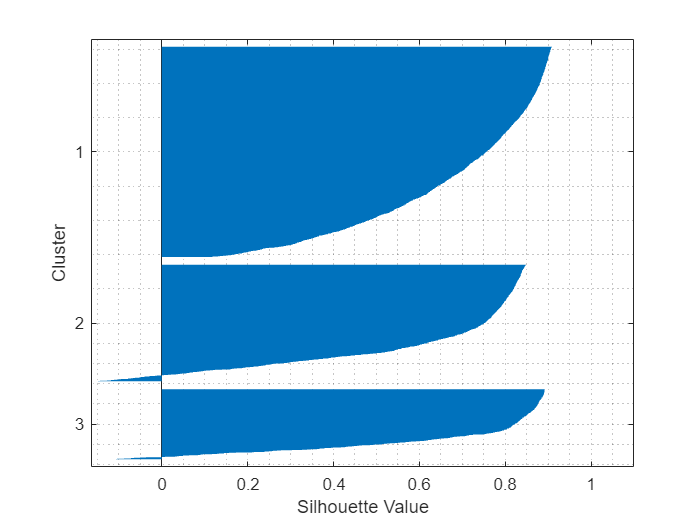

kGrp = kmeans(bonds, 3, "Distance", "cosine");
silhouette(bonds, kGrp, "cosine")
grid minor

## Task 2

eva = evalclusters(bonds, "kmeans", "silhouette",...
    "KList", 2:7, "Distance", "cosine")

eva =   SilhouetteEvaluation with properties:

    NumObservations: 4082
         InspectedK: [2 3 4 5 6 7]
    CriterionValues: [0.6696 0.6685 0.6516 0.5773 0.5566 0.5470]
           OptimalK: 2



numClust = eva.OptimalK

numClust = 2

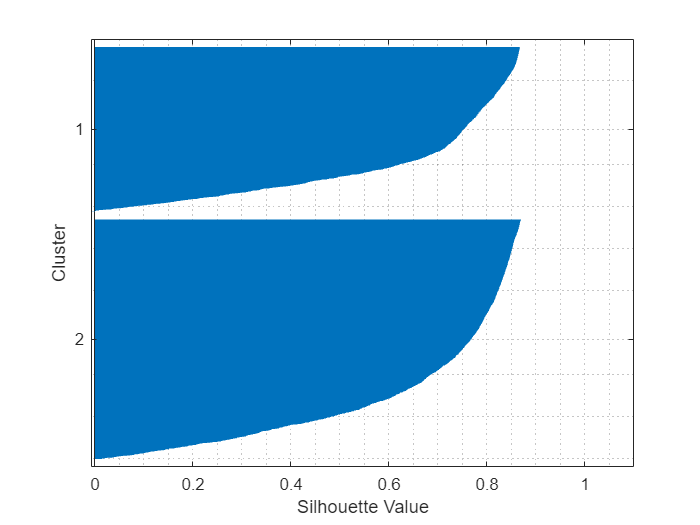

kGrp = kmeans(bonds, numClust, "Distance", "cosine");
silhouette(bonds, kGrp, "cosine")
grid minor